# **CLASIFICACIÓN NO LINEAL - RED NO PROFUNDA**

# 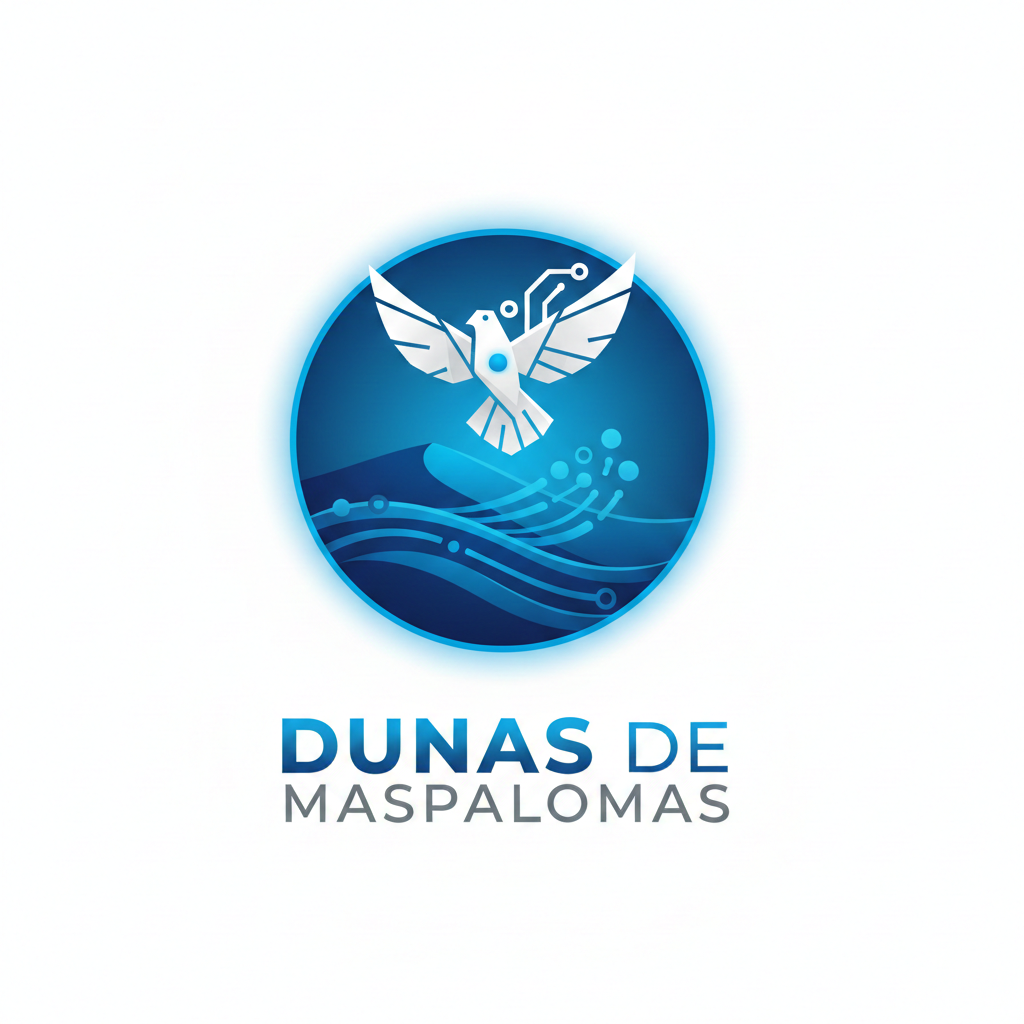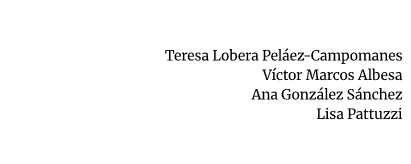

### 1.DECLARACIÓN DE PARÁMETROS

%Definición de los parametros
num_puntos=150;      
tasa_aprendizaje=0.05;   
num_epocas=1000000;  
probabilidad_lejos=0.4; 
prob_infiltrados=0.4;     

%Arquitectura MLP
capas_ocultas=[60]; 

%Configuración del GIF
nombre_gif='evolucion_mlp_superficial.gif'; 
num_frames=200; 
delay_normal=0.05; 
delay_final=3.0; 

### 2.GENERACIÓN DE DATOS

rng(3); 
N=num_puntos/2;
ancho_x=4; 
generar_distancias = @(n, prob, dist_min, dist_max_cerca, dist_min_lejos) ...
    ((rand(1, n) > prob) .* (dist_min + rand(1, n)*(dist_max_cerca-dist_min))) + ... 
    ((rand(1, n) <= prob) .* (dist_min_lejos + rand(1, n)*2)); 
% Clase 1 (Puntos Azules)
X1_x=(rand(1, N) - 0.5) * ancho_x; 
distancias_1=generar_distancias(N, probabilidad_lejos, 0.2, 0.8, 3.0);
signos_1=ones(1, N); 
mask_inf_1=rand(1, N) < prob_infiltrados;
signos_1(mask_inf_1)=-1;
X1_y=(X1_x .^ 2) + (distancias_1 .* signos_1) + (randn(1, N) * 0.1);

X1=[X1_x; X1_y]; 
Y1=ones(1, N);

X0_x=(rand(1, N) - 0.5) * ancho_x;
distancias_0=generar_distancias(N, probabilidad_lejos, 0.2, 0.8, 3.0);
signos_0=-ones(1, N); 
mask_inf_0=rand(1, N) < prob_infiltrados; 
signos_0(mask_inf_0)=1;
X0_y=(X0_x .^ 2) + (distancias_0 .* signos_0) + (randn(1, N) * 0.1);

X0=[X0_x; X0_y]; 
Y0=zeros(1, N);

X=[X0, X1]; 
Y=[Y0, Y1];
m=size(X, 2); 
mean_X=mean(X, 2); 
std_X=std(X, 0, 2);
X=(X - mean_X) ./ std_X;

### 3.INICIALIZACIÓN

topologia=[2, capas_ocultas, 1];
num_capas=length(topologia); 
L_weights=num_capas - 1;    

W=cell(1, L_weights);
b=cell(1, L_weights);

for l = 1:L_weights
    W{l}=randn(topologia(l+1), topologia(l)) * 0.1; 
    b{l}=zeros(topologia(l+1), 1);
end

sigmoid=@(z) 1 ./ (1 + exp(-z));
loss_history=nan(1, num_epocas); 

### 4.CONFIGURACIÓN DEL GIF

indices_frames=unique(round(logspace(0, log10(num_epocas), num_frames)));
fig=figure('Name', 'MLP Mono-Strato', 'Color', 'w', 'Position', [50, 50, 1100, 500]);

margin=0.5;
x_min=min(X(1,:)) - margin; x_max=max(X(1,:)) + margin;
y_min=min(X(2,:)) - margin; y_max=max(X(2,:)) + margin;
[xx, yy]=meshgrid(x_min:0.05:x_max, y_min:0.05:y_max);
grid_X=[xx(:)'; yy(:)'];

color_fondo_0=[1, 0.5, 0.5]; 
color_fondo_1=[0.4, 0.7, 1.0];
mapa_colores=[color_fondo_0; color_fondo_1];

### 5.CICLO DE ENTRENAMIENTO

Época 1, Coste: 0.7010


Época 2, Coste: 0.6984


Época 5, Coste: 0.6950
Época 10, Coste: 0.6939
Época 22, Coste: 0.6938
Época 46, Coste: 0.6936
Época 100, Coste: 0.6934
Época 215, Coste: 0.6930
Época 464, Coste: 0.6924
Época 1000, Coste: 0.6917


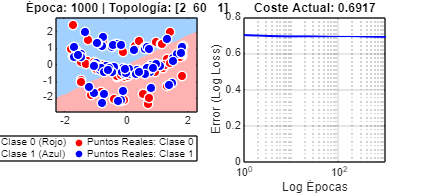

for i = 1:num_epocas
    A=cell(1, num_capas); 
    Z=cell(1, num_capas);
    A{1}=X; 
    for l = 1:L_weights
        Z{l+1}=W{l} * A{l} + b{l};
        A{l+1}=sigmoid(Z{l+1});
    end
    A_final=A{end};
    
    %Pérdida
    epsilon=1e-15; 
    A_clipped=max(min(A_final, 1-epsilon), epsilon);
    cost=-(1/m) * sum(Y.*log(A_clipped) + (1-Y).*log(1-A_clipped));
    loss_history(i)=cost;
    
    %Gradiente
    dW=cell(1, L_weights); 
    db=cell(1, L_weights);
    dZ=A_final - Y; 
    for l = L_weights:-1:1
        dW{l}=(1/m) * (dZ * A{l}');
        db{l}=(1/m) * sum(dZ, 2);
        if l > 1
            dA_prev=W{l}' * dZ;
            dZ=dA_prev .* (A{l} .* (1 - A{l}));
        end
    end
    
    %Actualización
    for l = 1:L_weights
        W{l}=W{l} - tasa_aprendizaje * dW{l};
        b{l}=b{l} - tasa_aprendizaje * db{l};
    end
    
    %GIF
    if ismember(i, indices_frames) || i == num_epocas
        if mod(i, 100) == 0 || i < 1000; fprintf('Época %i, Coste: %.4f\n',i, cost); end;

        A_grid=grid_X;
        for l = 1:L_weights
            Z_grid=W{l} * A_grid + b{l};
            A_grid=sigmoid(Z_grid);
        end
        % BINARIZAR: Si > 0.5 es Clase 1, si no Clase 0
        A_grid_binary=double(A_grid > 0.5); 
        A_grid_mesh=reshape(A_grid_binary, size(xx));
        
        % DIBUJO
        subplot(1, 2, 1);
        
        % Contourf con solo 1 nivel para separar los dos colores estrictamente
        contourf(xx, yy, A_grid_mesh, 1, 'LineColor', 'none', 'FaceAlpha', 0.6);
        
        % Aplicar mapa de colores de 2 filas
        colormap(gca, mapa_colores);
        clim([0, 1]); % Asegurar que 0 va al color 1 y 1 va al color 2
        hold on;
        
        %leyenda
        h_zona0=plot(NaN,NaN,'s', 'MarkerFaceColor', color_fondo_0, 'MarkerEdgeColor', 'none', 'DisplayName', 'Zona Predicha: Clase 0 (Rojo)');
        h_zona1=plot(NaN,NaN,'s', 'MarkerFaceColor', color_fondo_1, 'MarkerEdgeColor', 'none', 'DisplayName', 'Zona Predicha: Clase 1 (Azul)');
        
        %Puntos Reales
        h_p0=scatter(X(1, Y==0), X(2, Y==0), 50, 'r', 'filled', 'MarkerEdgeColor', 'w', 'LineWidth', 1, 'DisplayName', 'Puntos Reales: Clase 0');
        h_p1=scatter(X(1, Y==1), X(2, Y==1), 50, 'b', 'filled', 'MarkerEdgeColor', 'w', 'LineWidth', 1, 'DisplayName', 'Puntos Reales: Clase 1');
        hold off;
        
        %Crear Leyenda
        legend([h_zona0, h_zona1, h_p0, h_p1], 'Location', 'southoutside', 'NumColumns', 2);
        title(sprintf('Época: %d | Topología: [%s]', i, num2str(topologia)));
        axis tight;
        
        subplot(1, 2, 2);
        semilogx(1:num_epocas, loss_history, 'b', 'LineWidth', 1.5); 
        xlim([1, num_epocas]);
        % Asegurar que el eje Y del error no se comprima demasiado si el error explota al inicio
        ylim([0, max(loss_history(indices_frames(indices_frames<=i))) + 0.1]); 
        title(sprintf('Coste Actual: %.4f', cost));
        grid on; xlabel('Log Épocas'); ylabel('Error (Log Loss)');
        drawnow;
        
        % GIF
        frame=getframe(fig);
        im=frame2im(frame);
        [imind, cm]=rgb2ind(im, 256);
        current_delay=(i == num_epocas) * delay_final + (i ~= num_epocas) * delay_normal;
        
        if i == indices_frames(1)
            imwrite(imind, cm, nombre_gif, 'gif', 'Loopcount', inf, 'DelayTime', current_delay);
        else
            imwrite(imind, cm, nombre_gif, 'gif', 'WriteMode', 'append', 'DelayTime', current_delay);
        end
    end
end